# EEG Motor Imagery classification using CNN

## Load data

% "files" is the folder in which EGG data was downloaded form the open
% database
numberOfSubjects = 10;

if isfolder('files')
    dirs = string(split(genpath("files"), ';'));
    
    allFiles = strings(numberOfSubjects*12, 1);
    k = 1;
    
    for i = 1:numberOfSubjects
        files = struct2table(dir(string(dirs(i + 1))));
        files = files{7:2:end, 1};
        files = string(dirs(i + 1))+'\'+string(files);
        for j = 1:length(files)
            allFiles(k) = files(j);
            k = k + 1;
        end
    end
    
    eegData = getEEGfromFiles(allFiles);
else
    disp("Files folder not found! Download the data!")
end

%eegData = load('MatlabData/s007_all_3_30_filt_epoch.mat').EEG;
channelsOfInterest = ["C3..", "C4..", "Cz.."];
idx = findChannelsOfInteres(eegData(1), channelsOfInterest);

## Processing data

disp(" [ START ] Processing data...")

 [ START ] Processing data...


 [ OK ] 1 of 12 Ready...


 [ OK ] 2 of 12 Ready...


 [ OK ] 3 of 12 Ready...


 [ OK ] 4 of 12 Ready...


 [ OK ] 5 of 12 Ready...


 [ OK ] 6 of 12 Ready...


 [ OK ] 7 of 12 Ready...


 [ OK ] 8 of 12 Ready...


 [ OK ] 9 of 12 Ready...


 [ OK ] 10 of 12 Ready...


 [ OK ] 11 of 12 Ready...


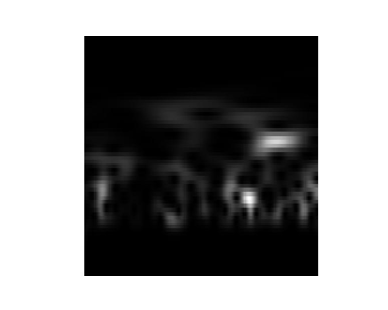

 [ OK ] 12 of 12 Ready...


totalEpochNumber = 0;
for i=1:length(eegData)
    totalEpochNumber = totalEpochNumber + eegData(i).trials;
end

xData = zeros(224, 224, length(idx), totalEpochNumber);
yData = categorical(zeros(totalEpochNumber, 1));
k = 1;
for j = 1:length(eegData)
    numTrials = eegData(j).trials;
    table = struct2table(eegData(j).event);
    for i = 1:numTrials
        xData(:, :, :, k) = getSpectrogramChannels(eegData(j).data, idx, [224 224], i);
        yData(k) = categorical(table{i, 1});
        k = k + 1;
    end
    disp(" [ OK ] "+j+" of "+length(eegData)+" Ready...")
end

yData = removecats(yData);
save("xData.mat", "xData")
save("yData.mat", "yData")
disp(" [ END ] DONE")

 [ END ] DONE


## Get even number of classes for training

numberOfT1 = nnz(yData == categorical({'T1'}));
newXtrain = zeros(224, 224, 3, 2*numberOfT1);
newYtrain = categorical(zeros(2*numberOfT1, 1))
k = 1;
for i = 1:2:2*numberOfT1
    for j = k:length(yData)
        if yData(j) == categorical({'T1'})
            k = j + 1;
            newXtrain(:, :, :, i) = xData(:, :, :, j);
            newYtrain(i) = yData(j);
            break;
        end
    end
end

k = 1;
for i = 2:2:2*numberOfT1
    for j = k:length(yData)
        if yData(j) == categorical({'T0'})
            k = j + 1;
            newXtrain(:, :, :, i) = xData(:, :, :, j);
            newYtrain(i) = yData(j);
            break;
        end
    end
end
newYtrain = removecats(newYtrain)
xTrain = newXtrain(:, :, :, 1:144);
yTrain = newYtrain(1:144);
xTest = newXtrain(:, :, :, 145:end);
yTest = newYtrain(145:end);

## CNN Training

%load("xData.mat")
%load("yData.mat")
n = length(xData);
trainLimit = ceil(n*0.6);
testLimit = ceil(n*0.2);
xTrain = xData(:, :, :, 1:trainLimit);
yTrain = yData(1:trainLimit);
xTest = xData(:, :, :, (trainLimit+1):(trainLimit+testLimit));
yTest = yData((trainLimit+1):(trainLimit+testLimit));
xVal = xData(:, :, :, (trainLimit+testLimit+1):end);
yVal = yData((trainLimit+testLimit+1):end);
valData = {xVal yVal};

options = trainingOptions( ...
    "sgdm", ...
    "Plots","training-progress", ...
    "InitialLearnRate",0.0001, ...
    "Shuffle","every-epoch", ...
    "ValidationData", valData, ... 
    "ValidationFrequency", 5, ...
    "ValidationPatience", 10 ...
)

% transfer learning
% net = trainNetwork(xTrain, yTrain, adaptedGnet, options)

% learning from scratch
layers = [
    imageInputLayer([224 224 3])
    convolution2dLayer(3, 16)
    ShufbatchNormalizationLayer
    reluLayer
    maxPooling2dLayer(2, "Stride",2)
    fullyConnectedLayer(2)
    softmaxLayer
    classificationLayer
]

net = trainNetwork(xTrain, yTrain, layers, options)

## Classification

[preds, scrs] = classify(net, xTest)

preds = 52×1 categorical array
     T1 
     T0 
     T1 
     T0 
     T0 
     T0 
     T0 
     T1 
     T1 
     T1 
     T1 
     T0 
     T0 
     T1 
     T1 
     T1 
     T1 
     T1 
     T1 
     T1 
     T0 
     T1 
     T0 
     T1 
     T1 
     T1 
     T1 
     T0 
     T0 
     T0 


scrs = 52×2 single matrix
    0.3511    0.6489
    0.8590    0.1410
    0.3665    0.6335
    0.8799    0.1201
    0.5800    0.4200
    0.9219    0.0781
    0.9777    0.0223
    0.0362    0.9638
    0.1721    0.8279
    0.0131    0.9869


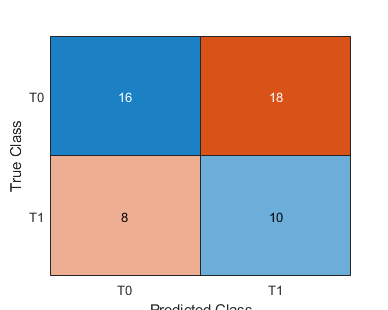

confusionchart(yTest, preds)

loss = nnz(yTest ~= preds)/length(preds)

loss = 0.5000

[preds, scrs] = classify(net, xVal)

preds = 51×1 categorical array
     T0 
     T0 
     T0 
     T0 
     T0 
     T0 
     T0 
     T0 
     T1 
     T0 
     T1 
     T0 
     T0 
     T0 
     T1 
     T0 
     T0 
     T1 
     T0 
     T1 
     T0 
     T0 
     T1 
     T0 
     T0 
     T0 
     T1 
     T0 
     T0 
     T1 


scrs = 51×2 single matrix
    0.9832    0.0168
    0.5650    0.4350
    0.5511    0.4489
    0.9390    0.0610
    0.5351    0.4649
    0.7125    0.2875
    0.7756    0.2244
    0.5063    0.4937
    0.1660    0.8340
    0.7265    0.2735


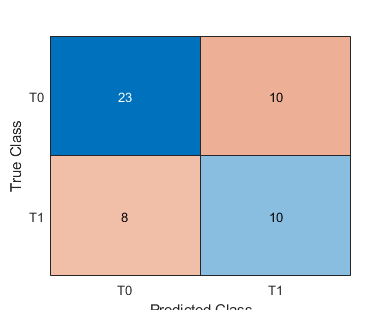

confusionchart(yVal, preds)

loss = nnz(yVal ~= preds)/length(preds)

loss = 0.3529

[preds, scrs] = classify(net, xTrain)

preds = 155×1 categorical array
     T1 
     T1 
     T1 
     T0 
     T0 
     T1 
     T0 
     T1 
     T1 
     T1 
     T0 
     T1 
     T1 
     T1 
     T1 
     T0 
     T1 
     T1 
     T1 
     T0 
     T0 
     T0 
     T1 
     T0 
     T1 
     T1 
     T1 
     T0 
     T1 
     T0 


scrs = 155×2 single matrix
    0.0172    0.9828
    0.4648    0.5352
    0.3103    0.6897
    0.5912    0.4088
    0.6910    0.3090
    0.3247    0.6753
    0.7879    0.2121
    0.0752    0.9248
    0.3597    0.6403
    0.0460    0.9540


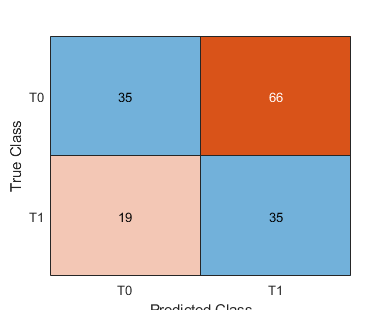

confusionchart(yTrain, preds)

loss = nnz(yTrain ~= preds)/length(preds)

loss = 0.5484

[preds, scrs] = classify(net, xData)

preds = 258×1 categorical array
     T1 
     T1 
     T1 
     T0 
     T0 
     T1 
     T0 
     T1 
     T1 
     T1 
     T0 
     T1 
     T1 
     T1 
     T1 
     T0 
     T1 
     T1 
     T1 
     T0 
     T0 
     T0 
     T1 
     T0 
     T1 
     T1 
     T1 
     T0 
     T1 
     T0 


scrs = 258×2 single matrix
    0.0172    0.9828
    0.4648    0.5352
    0.3103    0.6897
    0.5912    0.4088
    0.6910    0.3090
    0.3247    0.6753
    0.7879    0.2121
    0.0752    0.9248
    0.3597    0.6403
    0.0460    0.9540


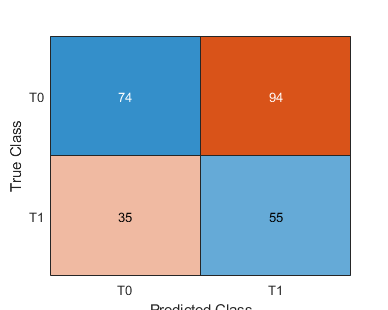

confusionchart(yData, preds)

loss = nnz(yData ~= preds)/length(preds)

loss = 0.5000

net = load("net.mat").net
xTest1 = load("xTest.mat").xTest;
yTest1 = load("yTest.mat").yTest;
imshow(xTest1(:, :, 1, 1))
imshow(xTest(:, :, 1, 1))
nnz(xTest1(:, :, 1, 1) == xTest(:, :, 1, 1))
           
[preds, ~] = classify(net, xTest1);            

function channelsOut=getSpectrogramChannels(eegData, idx, size, epoch)
    channelsOut = zeros([size length(idx)]);
    
    for i = 1:length(idx)
        coefs = cwt(eegData(idx(i), :, epoch));
        wscalogram('image', coefs);
        colormap('gray');
        title('')
        colorbar off
        axis off
        saveas(gcf, "image.jpg");
        im = imread("image.jpg");
        im = RemoveWhiteSpace(im);
        im = imresize(im, size);
        imshow(im);
        channelsOut(:, :, i) = im(:, :, 1);
    end
end

function idx=findChannelsOfInteres(eegSet, channelsOfInterest)
    table = struct2table(eegSet.chanlocs);
    a = string(table.labels);
    idx = zeros(length(channelsOfInterest), 1);
    
    for i = 1:length(a)
        for j=1:length(channelsOfInterest)
            if channelsOfInterest(j) == a(i)
                idx(j) = i;
                break
            end
        end
    end
end

function eeg = getEEGfromFiles(files) 
    for i = 1:length(files)
        data = pop_biosig(char(files(i)));
        
        % extracting only relevant frequency bands 
        % for motor imagery classification
        data = pop_eegfilt(data, 8, 30);
        
        data = pop_epoch(data, {'T0', 'T1'}, [-1 2]);
        eeg(i) = data;
    end
end